# Updated External-Forces Tester

This live-script source wraps the shared tester runner so the validation cases always use the current aircraft and scenario definitions.

It is the maintainable source for TESTER_external_forces_updated.mlx.

clear; clc;

script_file = localGetThisFile();
if ~isempty(script_file)
    addpath(fileparts(script_file));
end

## Options

Leave requestedCases empty to run all six cases.

requestedCases = {};

% Set these flags before running the script.
showRender = true;
makePlots = true;
replayFlightGear = false;
replayCase = 'Case 5 - Cruise Beta to Yaw';

## Preview Test Matrix

The runner prints this summary too, but it is helpful to keep it visible in the live script before the simulation output starts.

previewOutputs = TESTER_external_forces_runner( ...
    'Cases', requestedCases, ...
    'ShowRender', false, ...
    'MakePlots', false, ...
    'PreviewOnly', true);

Updated tester run using aircraft_def.m / scenario_def.m
Repository root: /Users/zbrown/Documents/Fifth year Spring/Flight Controls/eVTOL-Flight-Sim
Test case summary:
                   Name                             Model                                              Purpose                                                                                                     Expected                                                                                                                    Basis                                                 
    ___________________________________    _______________________    __________________________________________________________________________    _______________________________________________________________________________________________________________________________________    <s

caseSummary = previewOutputs.case_summary

caseSummary = 6×5 table
                   Name                             Model                                              Purpose                                                                                                     Expected                                                                                                                    Basis                                                 
    ___________________________________    _______________________    __________________________________________________________________________    _______________________________________________________________________________________________________________________________________    ______________________________________________________________________________________________________

    "Case 1 - Inertia Cou

## Run Validation Cases

Updated tester run using aircraft_def.m / scenario_def.m
Repository root: /Users/zbrown/Documents/Fifth year Spring/Flight Controls/eVTOL-Flight-Sim
Aero surface normal vectors:
  L Main Wing pos = [ -0.50  -3.75  -0.60], n = [ 0.00  0.00 -1.00]
  R Main Wing pos = [ -0.50   3.75  -0.60], n = [ 0.00  0.00 -1.00]
  L V-Tail   pos = [ -3.50  -0.71  -0.91], n = [ 0.00  0.71 -0.71]
  R V-Tail   pos = [ -3.50   0.71  -0.91], n = [ 0.00 -0.71 -0.71]
Propeller thrust vectors:
  FR1  hub = [  1.95   1.80  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  FL1  hub = [  1.95  -1.80  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  FR2  hub = [  1.95   4.20  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  FL2  hub = [  1.95  -4.20  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  FR3  hub = [  1.95   6.50  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  FL3  hub = [  1.95  -6.50  -0.95], tilt =   0.0 deg, thrust = [ 0.00  0.00 -1.00]
  RR1  hub = [ -2.20  

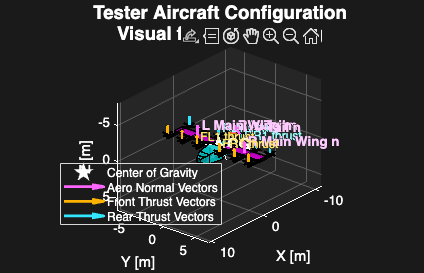

Test case summary:
                   Name                             Model                                              Purpose                                                                                                     Expected                                                                                                                    Basis                                                 
    ___________________________________    _______________________    __________________________________________________________________________    _______________________________________________________________________________________________________________________________________    ______________________________________________________________________________________________________

    "Case 1 - Inertia Coupling

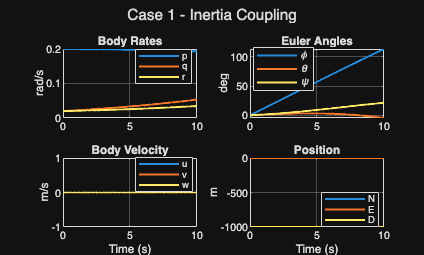

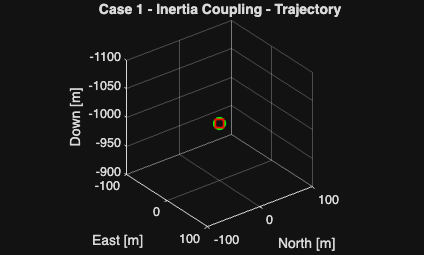

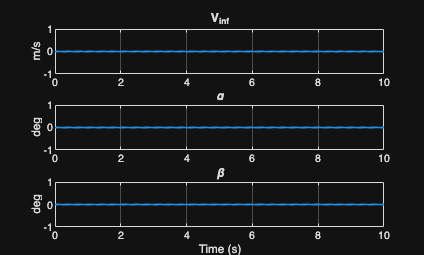

Checks that the updated inertia matrix produces sensible rigid-body coupling.
--------------------------------------------------
Case 2 - 95% Weight Support
--------------------------------------------------
  Model:            TESTER_Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [0  0  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  9.81] m/s^2
  Fext_B:           [0  0  -28331.3] N
  Mext_B:           [0  0  0] N-m
  Front Tilt:       0 deg
  Purpose:          Vertical force-balance test using the current modeled aircraft weight.
  Expected:         Vehicle should descend slowly because external support is slightly smaller than weight.
 


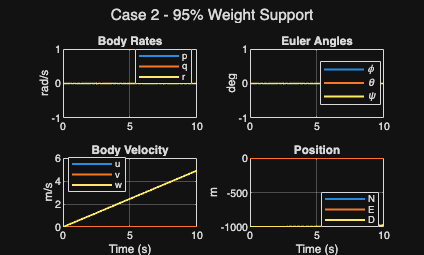

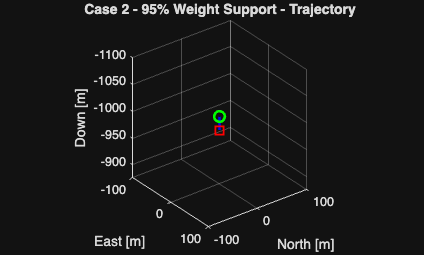

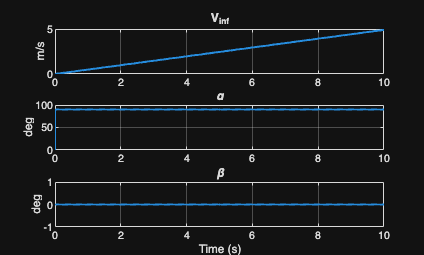

Checks that the tester model responds correctly to near-balanced external lift.
--------------------------------------------------
Case 3 - Pitch Moment Step
--------------------------------------------------
  Model:            TESTER_Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [0  0  0] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  3000  0] N-m
  Front Tilt:       0 deg
  Purpose:          Pure pitch-moment response using the current aircraft pitch inertia.
  Expected:         Pitch rate should grow in the commanded direction with only small translation or roll/yaw coupling.
 


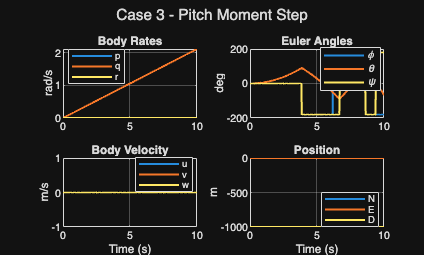

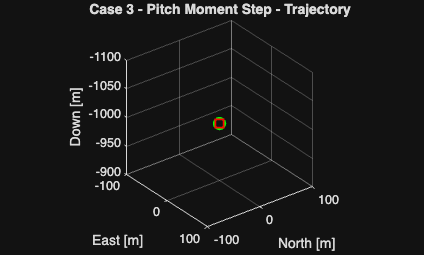

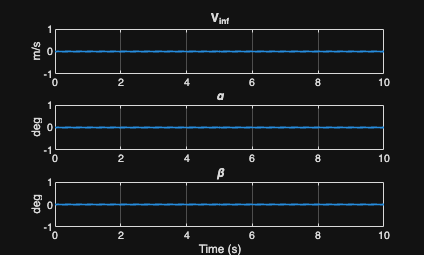

Checks that the updated pitch inertia produces a believable angular-acceleration response.
--------------------------------------------------
Case 4 - Roll Damping
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [55  0  5] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0.08  0  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
  Front Tilt:       90 deg
  Purpose:          Aerodynamic roll-rate damping in a plausible cruise condition.
  Expected:         Roll rate should damp over time and may couple into yaw/pitch because of the V-tail and non-diagonal inertia.
 


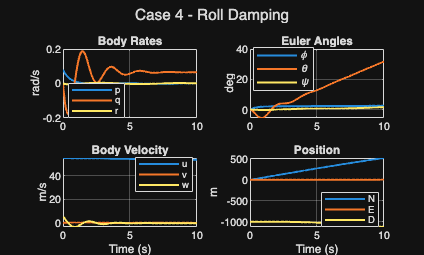

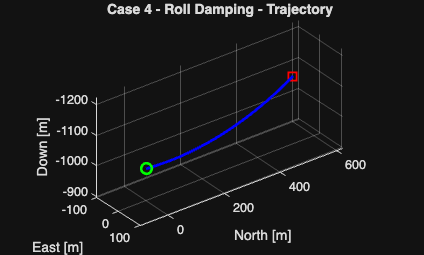

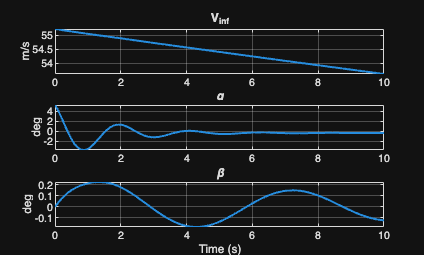

Replaces the old 250 m/s placeholder with a cruise-speed value that matches the current wing loading much better.
--------------------------------------------------
Case 5 - Cruise Beta to Yaw
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [55  5  5] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  0] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
  Front Tilt:       90 deg
  Purpose:          Sideslip-to-yaw/roll coupling check at a plausible cruise speed.
  Expected:         The aircraft should show a yawing and rolling response that tends to react to the initial sideslip.
 


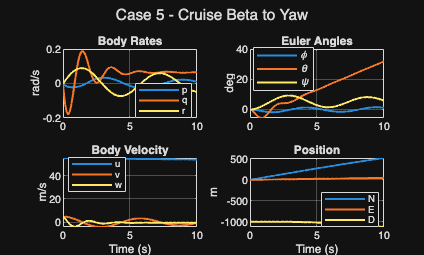

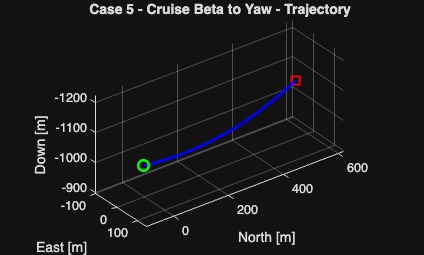

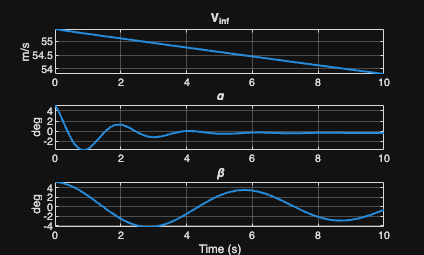

Checks whether the updated V-tail and wing aero data produce reasonable directional coupling.
--------------------------------------------------
Case 6 - Unpowered Glide Response
--------------------------------------------------
  Model:            Brown_Full_Sim
  Simulation Time:  10 s
  Initial Position: [0  0  -1000] m
  Initial Velocity: [55  0  5] m/s
  Initial Euler:    [0  0  0] deg
  Initial Omega:    [0  0  0] rad/s
  Gravity:          [0  0  -9.81] m/s^2
  Fext_B:           [0  0  0] N
  Mext_B:           [0  0  0] N-m
  Front Tilt:       90 deg
  Purpose:          Unpowered full-model response with gravity enabled.
  Expected:         Aircraft should descend and adjust its attitude/velocity rather than hold level trim, because this is not a trimmed flight condition.
 


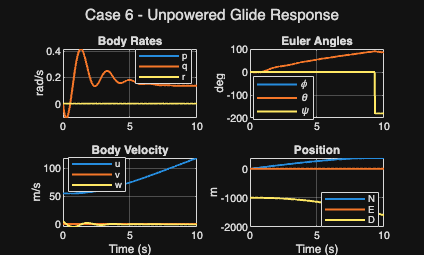

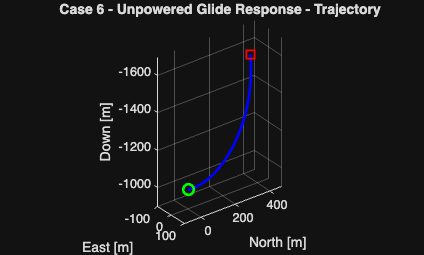

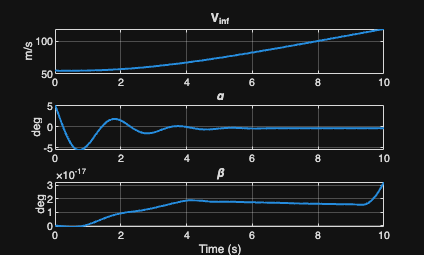

Serves as a gravity-plus-aerodynamics sanity check without relying on the still-unvalidated propulsion model.


outputs = TESTER_external_forces_runner( ...
    'Cases', requestedCases, ...
    'ShowRender', showRender, ...
    'MakePlots', makePlots, ...
    'ReplayFlightGear', replayFlightGear, ...
    'ReplayCase', replayCase);

## Output Summary

disp('Completed tester cases:');

Completed tester cases:


disp(setdiff(fieldnames(outputs), {'case_summary'}));

    {'Case1_InertiaCoupling'       }
    {'Case2_95_WeightSupport'      }
    {'Case3_PitchMomentStep'       }
    {'Case4_RollDamping'           }
    {'Case5_CruiseBetaToYaw'       }
    {'Case6_UnpoweredGlideResponse'}



## Notes

This script intentionally delegates the actual setup/sim logic to TESTER_external_forces_runner.m so the aircraft definition only lives in one place.

function script_file = localGetThisFile()
script_file = mfilename('fullpath');
if ~isempty(script_file)
    return;
end

script_file = '';
try
    script_file = matlab.desktop.editor.getActiveFilename;
catch
    % Fall back to the current folder if the editor API is unavailable.
end
end